# ABR Class Demo

clearvars
close all
clc

## Create a simple ABR object 

% Define the properties of the ABR

amplitude = randn(100,1); % Vector of the amplitude values
fs = 10000; % Sample Rate
level = 50; % Level of recording
side = "derecha"; % Side
subjectID = "sujeto1"; % Subject Identificator
label = "ejemplo"; % A custom label to name the ABR (optional)

% Create the ABR object from those properties
abrObject = ABR('amplitude', amplitude, 'fs', fs, 'level', level, 'side', side, 'subjectID', subjectID, 'label', label)

abrObject =   ABR with properties:

     amplitude: [100×1 double]
            fs: 10000
         level: 50
          side: "derecha"
     subjectID: "sujeto1"
         label: "ejemplo"
      timeUnit: 's'
       ampUnit: 'V'
     timeScale: unit
      ampScale: unit
    timeVector: [1×100 double]
       Npoints: 100
    noiseLevel: [1.5245 -0.9433]


## Create an ABR object from text file

filename = '19004_izq_abr1.txt'; % Edit this line to change the ABR file (don't forget the externsion .txt)

Create an array of ABR objects containing each recording in the file

abr = ABR.openFile(filename);
abr(1)

ans =   ABR with properties:

     amplitude: [244×1 double]
            fs: 2.4414e+04
         level: 0
          side: "IZQ"
     subjectID: "19001"
         label: "19004_izq_abr1_0dB"
      timeUnit: 's'
       ampUnit: 'V'
     timeScale: unit
      ampScale: unit
    timeVector: [1×244 double]
       Npoints: 244
    noiseLevel: [2.9325e-06 -2.4746e-06]


If the file is not specified, then it can be selected manually from the browser

abr = ABR.openFile();


## ABR Operations

### Addition of two ABRs

% Open a new ABR
filename1 = '19004_izq_abr1.txt';
abr1 = ABR.openFile(filename1);

% Add the 2nd (Level = 10 dB) ABR with the 9th (Level = 80 dB)
S = abr1(2) + abr1(9)

S =   ABR with properties:

     amplitude: [244×1 double]
            fs: 2.4414e+04
         level: []
          side: ''
     subjectID: ''
         label: ''
      timeUnit: 's'
       ampUnit: 'V'
     timeScale: unit
      ampScale: unit
    timeVector: [1×244 double]
       Npoints: 244
    noiseLevel: [3.0408e-06 -3.4754e-06]



% NB: to be added together, ABRs must have the exact same time vector (i.e.
% size and sample rate).

### Sum of several ABRs

% Sum ABRs 3 (level = 20 dB), 7 (level = 60 dB), 8 (level = 70 dB) and 9
% (level = 80 dB)

% In the resulting ABR, the properties "level", "side", "subjectID" and
% "label" are left empty
result = sum(abr1([3 7 8 9]))

result =   ABR with properties:

     amplitude: [244×1 double]
            fs: 2.4414e+04
         level: []
          side: ''
     subjectID: ''
         label: ''
      timeUnit: 's'
       ampUnit: 'V'
     timeScale: unit
      ampScale: unit
    timeVector: [1×244 double]
       Npoints: 244
    noiseLevel: [8.5796e-06 -8.5072e-06]


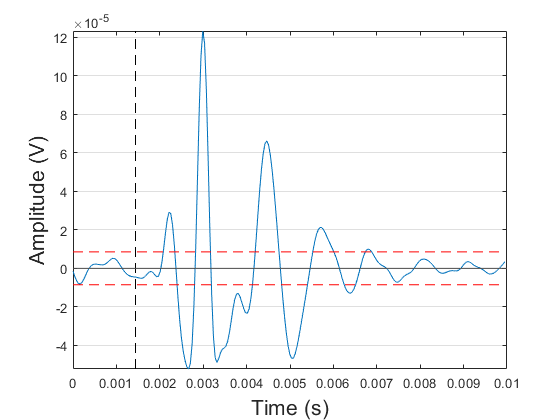

result.plot

### Average several ABRs

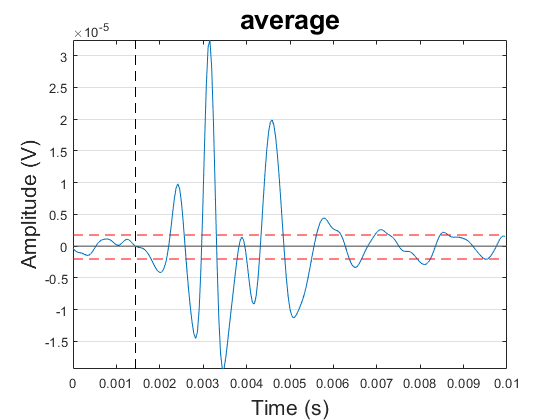

% Use the mean command as on an array of ABRs, just as any array of
% numbers.

% Averaging the ABRs 5 and 6
averagedABR = mean(abr1(5:6));
averagedABR.plot

### Average ABRs from different files

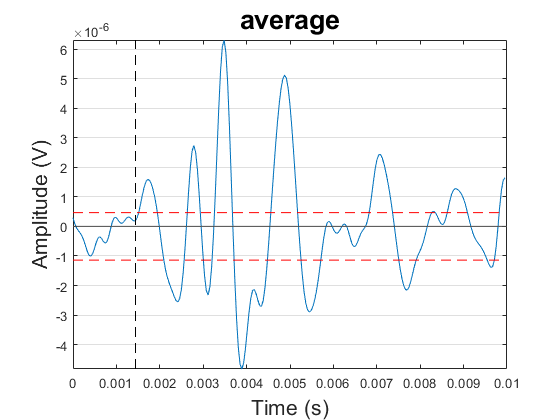

% import other ABR objects in the workspace
filename2 = '19004_izq_abr1.txt';
abr2 = ABR.openFile(filename2);

% Concatenate the ABRs you want to average

averagedABR = mean([abr1(1:3) abr2(1:3)]); % average the 3 first ABRs from filename1 with the 3 first from filename 2
averagedABR.plot


S = sum([abr1 abr2]);

## ABR Visualization

### Plot all ABR recordings

Each abr recording is plotted in individual figures

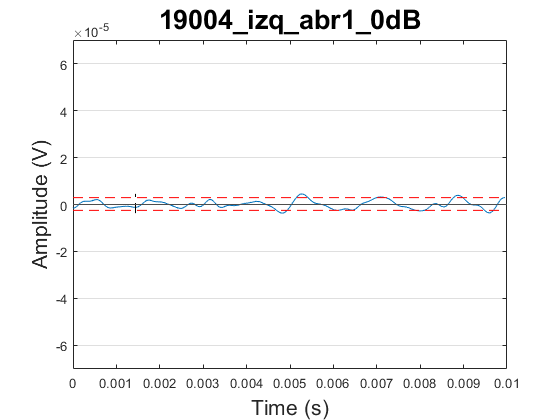

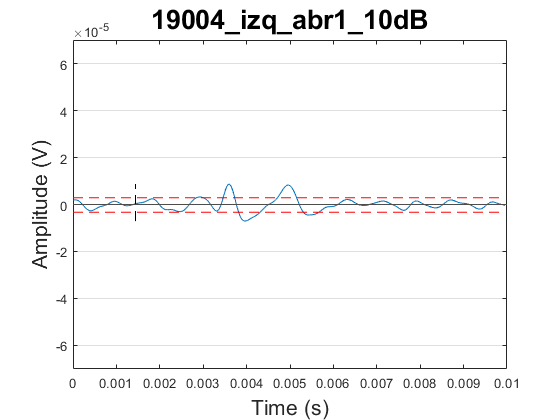

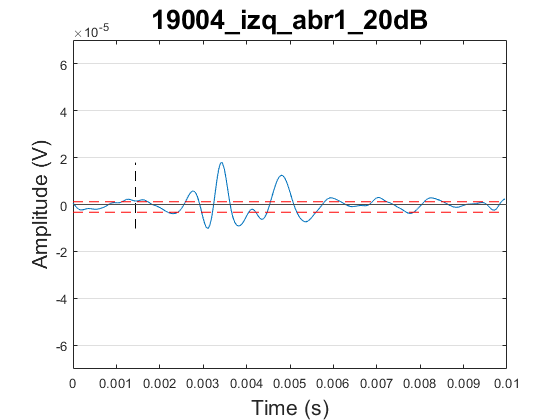

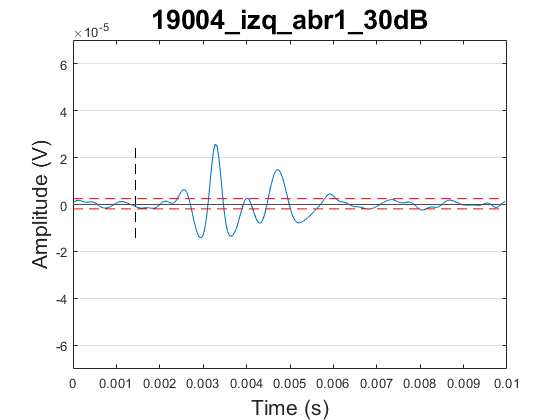

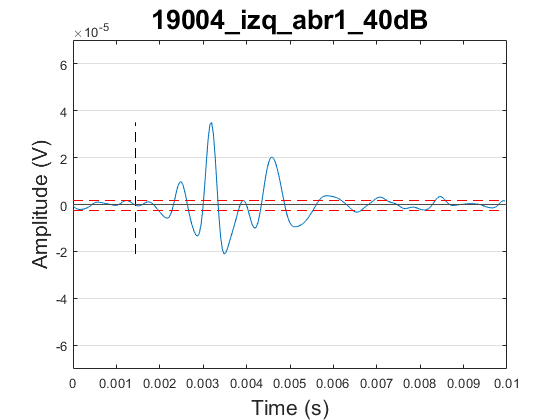

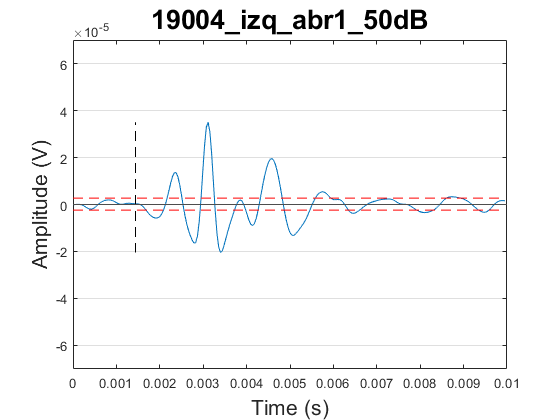

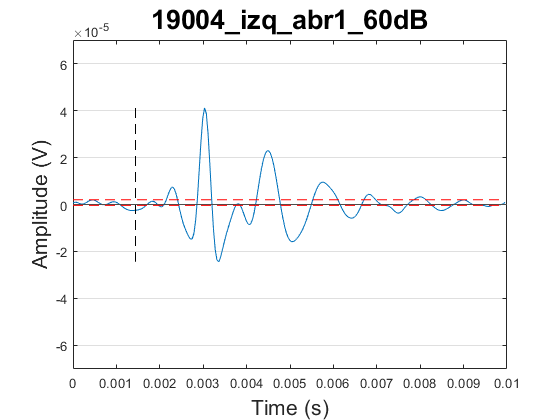

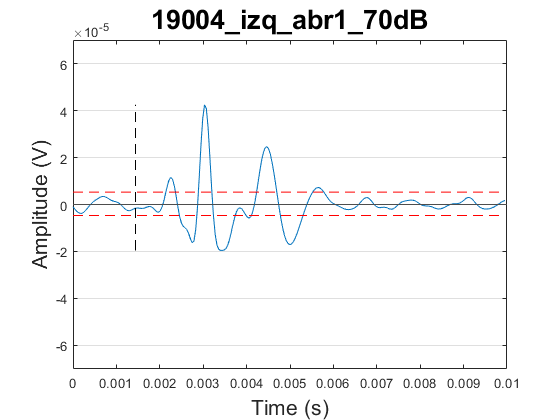

abr.plot('YLim', [-7e-5 7e-5])

## Plot specific ABR

### By linear indexing

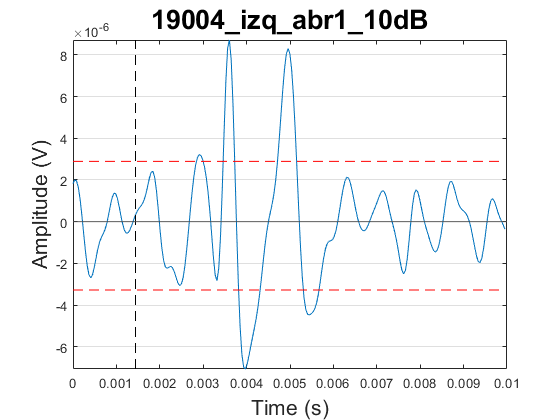

abr(2).plot

### Indexing by level

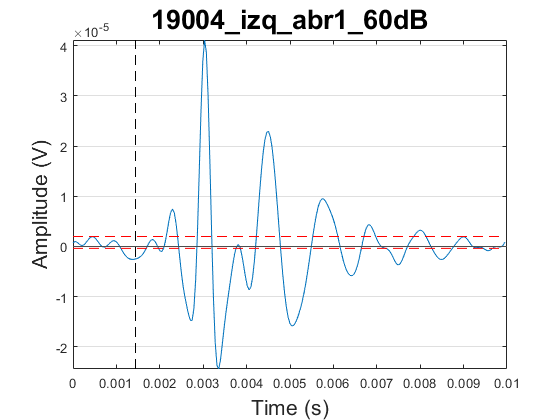

level = 60;
abr([abr.level] == level).plot

### Changing the plot properties

Line properties could be passed as input arguments within the plot function as usual.

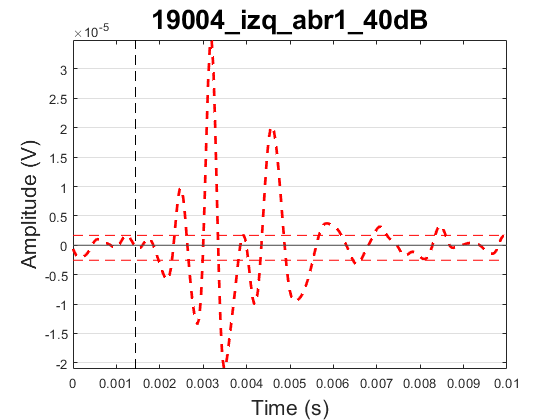

abr(5).plot('r', 'LineWidth', 2, 'LineStyle', '--')

### Changing the time and amplitude units

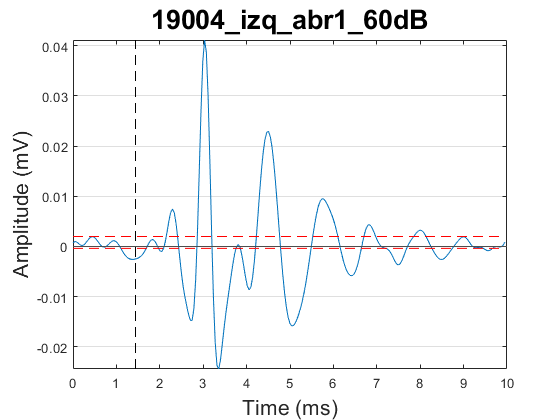

abr(7).plot('timeunit', 'ms', 'ampunit', 'mV')

### Changing the amplitude range

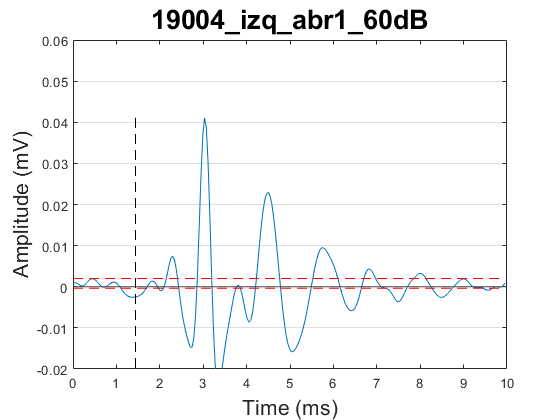

abr(7).plot('timeunit', 'ms', 'ampunit', 'mV', 'YLim', [-0.02 0.06])

## Open ABR in Graphical User Interface (GUI)

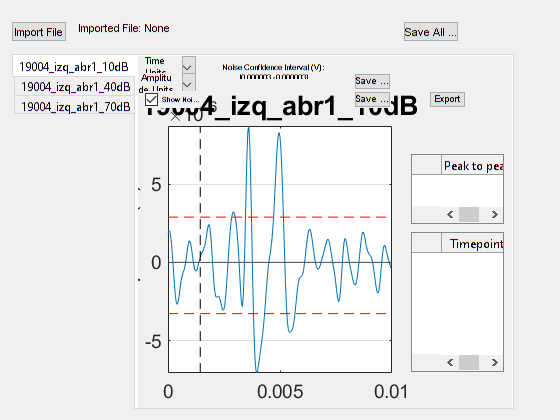

abr(5).openInGUI % Open a specific abr

abr([2 5 8]).openInGUI % Open several ABRs in GUI

## Export ABRs

### Into Excel sheet

Each sheet is named after the SubjectID of the txt file

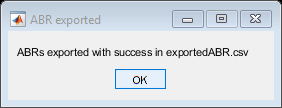

filename = 'exportedABR.csv';
abr.export(filename)